# `Second-order systems analysis`

`A program to quickly and easily solve second order systems`

`Created by Sam Scott on 18/05/22`

`Includes:`

`Open loop control analysis`

- `Step response`

- `Numerical Step info`

- `General second order system approximation (natural freq, damping ratio etc)`

- `Step info calculated from general second order equation soloutions`

- `DC gain calculation`

- `Poles and zeros`

- `Frequency response with bandwidth calculation`

`Closed loop control analysis`

- `Above and`

- `PID controller input`

- `Sensitivity analysis.`

#### `Setup`

s = tf('s');


% Plant transfer function 
numerator = 1; % replace as appropriate
A = 2;   % Replace coefficients as appropriate
B = 2;
C = 3;
denominator = ( (A)*s^2 + (B)*s + (C) ); 
G = (numerator / denominator)

G =
 
         1
  ---------------
  2 s^2 + 2 s + 3
 
Continuous-time transfer function.



## `Open loop control`

#### 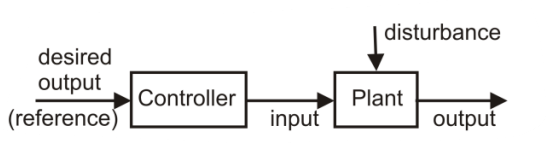

% Open loop control analysis
fprintf("\n\nOpen Loop control:\n-------------------------------------------------");



Open Loop control:
-------------------------------------------------


% Controller
openLoopController = 1; % change as appropriate

oLT = (openLoopController*G) % open loop transfer function

oLT =
 
         1
  ---------------
  2 s^2 + 2 s + 3
 
Continuous-time transfer function.



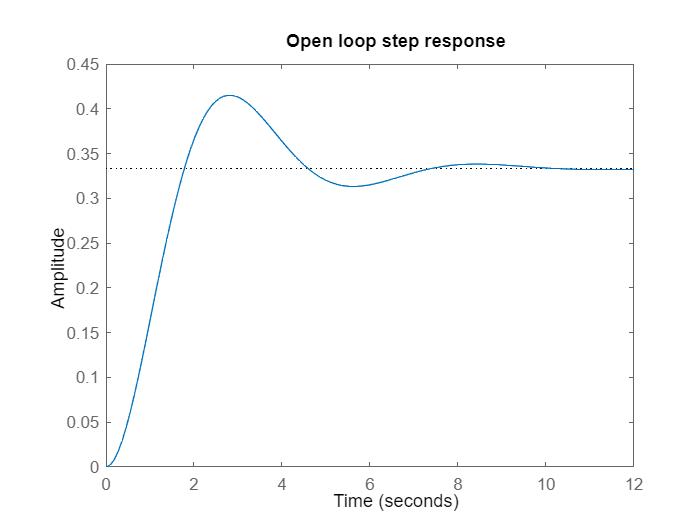


% Step response
stepMagnitude = 1;
openLoopStep = step(oLT*stepMagnitude);
step(oLT*stepMagnitude)
title("Open loop step response")


% numerical step info
openLoopNumericalStepInfo = stepinfo(oLT*stepMagnitude)

openLoopNumericalStepInfo = struct with fields:
         RiseTime: 1.2078
    TransientTime: 6.8644
     SettlingTime: 6.8644
      SettlingMin: 0.3114
      SettlingMax: 0.4150
        Overshoot: 24.5005
       Undershoot: 0
             Peak: 0.4150
         PeakTime: 2.8552



% A general second order system 
[num, den] = tfdata(oLT); num = cell2mat(num); den = cell2mat(den);

naturalFrequency = sqrt( (den(3) /  den(1)) ); % sqrt(C/A)
zeta = den(2) / (2*den(1)*naturalFrequency);
dampedNaturalFrequency = naturalFrequency*sqrt(1-zeta^2);

% calculated step info from equations below
riseTimeTr1 = (2.16*zeta + 0.6) / naturalFrequency;
settlingTimeTs = 4 / (zeta*naturalFrequency);
overshootPO = 100*exp( (-zeta*pi) / (sqrt(1-zeta^2)) );
fprintf("\nCalculated step info from equations:\n    Rise time: %f (s)\n    Settling time(2%%): %f (s)\n    Percentage overshoot: %f %%" ...
        , riseTimeTr1, settlingTimeTs, overshootPO)


Calculated step info from equations:
    Rise time: 1.209898 (s)
    Settling time(2%): 8.000000 (s)
    Percentage overshoot: 24.537615 %



openLoopDCGain = dcgain(oLT)

openLoopDCGain = 0.3333


[openLoopPoles, openLoopZeros] = pzmap(oLT)

openLoopPoles =   -0.5000 + 1.1180i
  -0.5000 - 1.1180i



openLoopZeros =

  0×1 empty double column vector








fprintf("---------------------------------------\n\nA General second order system: - open loop\n\n")

---------------------------------------

A General second order system: - open loop




fprintf("Natural frequency (omega_n):           %f (rad/s)\n", naturalFrequency)

Natural frequency (omega_n):           1.224745 (rad/s)



fprintf("Damping ratio (zeta):                  %f \n", zeta)

Damping ratio (zeta):                  0.408248 



fprintf("Damped natural frequency (omega_d):    %f (rad/s)\n", dampedNaturalFrequency)

Damped natural frequency (omega_d):    1.118034 (rad/s)





% Frequency analysis
fprintf("---------------------------------------\n\nOpen loop frequency response\n\n")

---------------------------------------

Open loop frequency response



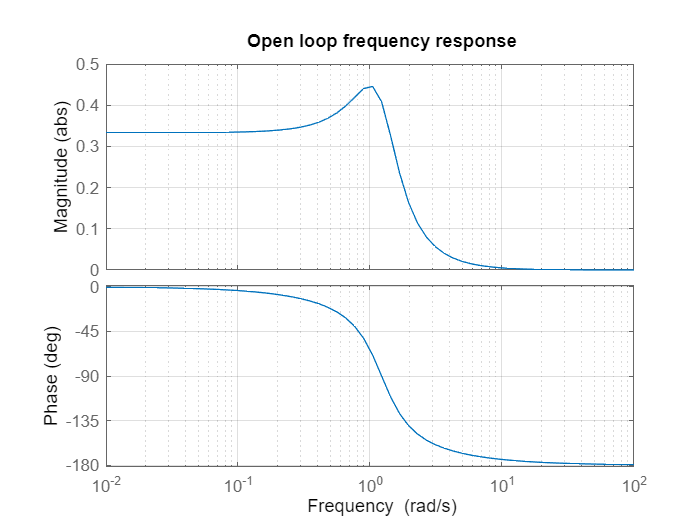

%omega = logspace(0, 100, 10000);
h = bodeplot(oLT);
title("Open loop frequency response")
% For absolute units in Hz:
%setoptions(h,'FreqUnits','Hz','MagUnits', 'Abs');

% For absolute units in rad/s
setoptions(h, 'MagUnits', 'Abs')

grid on



% Finding bandwidth
bw = bandwidth(oLT);
fprintf("\nBandwidth: %f (rad/s) == %f (Hz)\n\n\n\n\n\n\n------------------------------------------------", bw, (bw/(2*pi)))


Bandwidth: 1.673265 (rad/s) == 0.266308 (Hz)






------------------------------------------------

#### `Useful equations`

`Time to first peak  |  Percentage overshoot  |  Damped natural frequency   |   Settling time (2%)`


$$T_p = \frac{\pi}{\omega_n\sqrt{1-\zeta^2}}$$
       
$${\%OS = PO = e^{\frac{-\zeta \pi}{\sqrt{1-\zeta^2}}}\times100 }$$
       
$$\omega_d = \omega_n\sqrt{1-\zeta^2}$$
              
$$T_s = \frac4{\zeta \omega_n}$$


`Rise time (10% to 90%)`


$$T_{r_1} = \frac{2.16\zeta + 0.6}{\omega_n}$$


## `Closed loop control`

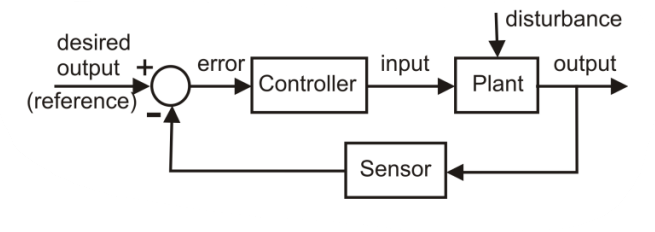

% Closed loop control analysis - Plant: G
fprintf("\n\nClosed Loop control: CHECK THAT ITS SECOND ORDER\n-------------------------------------------------");



Closed Loop control: CHECK THAT ITS SECOND ORDER
-------------------------------------------------


% Controller - PID
Kp = 1; % change as appropriate
Ki = 0;
Kd = 0;
closedLoopController = Kp + Ki/s + s*Kd; 

% assuming unity feedback
cLT = (feedback(closedLoopController*G, 1)) % closed loop transfer function

cLT =
 
         1
  ---------------
  2 s^2 + 2 s + 4
 
Continuous-time transfer function.



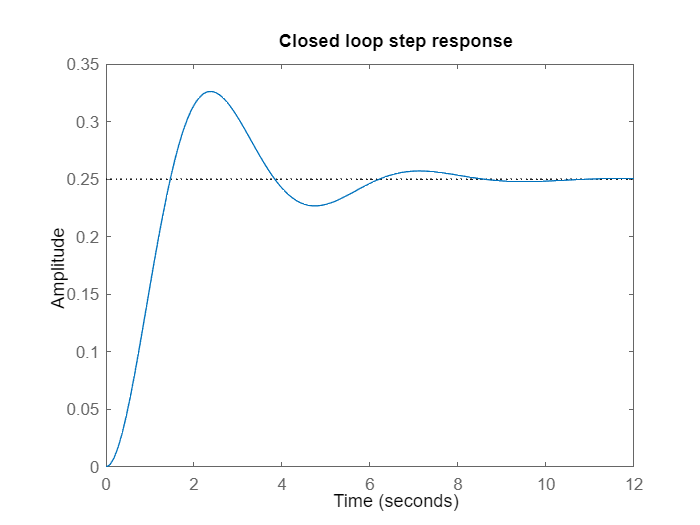


% Step response
stepMagnitude = 1;
closedLoopStep = step(cLT*stepMagnitude);
step(cLT*stepMagnitude)
title("Closed loop step response")

% numerical step info
closedLoopNumericalStepInfo = stepinfo(cLT*stepMagnitude)

closedLoopNumericalStepInfo = struct with fields:
         RiseTime: 0.9887
    TransientTime: 7.7420
     SettlingTime: 7.7420
      SettlingMin: 0.2268
      SettlingMax: 0.3262
        Overshoot: 30.4890
       Undershoot: 0
             Peak: 0.3262
         PeakTime: 2.3947



% A general second order system 
[num, den] = tfdata(cLT); num = cell2mat(num); den = cell2mat(den);

naturalFrequency = sqrt( (den(3) /  den(1)) ); % sqrt(C/A)
zeta = den(2) / (2*den(1)*naturalFrequency);
dampedNaturalFrequency = naturalFrequency*sqrt(1-zeta^2);

% calculated step info from equations above
riseTimeTr1 = (2.16*zeta + 0.6) / naturalFrequency;
settlingTimeTs = 4 / (zeta*naturalFrequency);
overshootPO = 100*exp( (-zeta*pi) / (sqrt(1-zeta^2)) );
fprintf("\nCalculated step info from equations:\n    Rise time: %f (s)\n    Settling time(2%%): %f (s)\n    Percentage overshoot: %f %%" ...
        , riseTimeTr1, settlingTimeTs, overshootPO)


Calculated step info from equations:
    Rise time: 0.964264 (s)
    Settling time(2%): 8.000000 (s)
    Percentage overshoot: 30.501009 %



closedLoopDCGain = dcgain(cLT)

closedLoopDCGain = 0.2500


[closedLoopPoles, closedLoopZeros] = pzmap(cLT)

closedLoopPoles =   -0.5000 + 1.3229i
  -0.5000 - 1.3229i



closedLoopZeros =

  0×1 empty double column vector








fprintf("---------------------------------------\n\nA General second order system: - closed loop\n\n")

---------------------------------------

A General second order system: - closed loop




fprintf("Natural frequency (omega_n):           %f (rad/s)\n", naturalFrequency)

Natural frequency (omega_n):           1.414214 (rad/s)



fprintf("Damping ratio (zeta):                  %f \n", zeta)

Damping ratio (zeta):                  0.353553 



fprintf("Damped natural frequency (omega_d):    %f (rad/s)\n", dampedNaturalFrequency)

Damped natural frequency (omega_d):    1.322876 (rad/s)





% Frequency analysis
fprintf("---------------------------------------\n\nClosed loop frequency response\n\n")

---------------------------------------

Closed loop frequency response



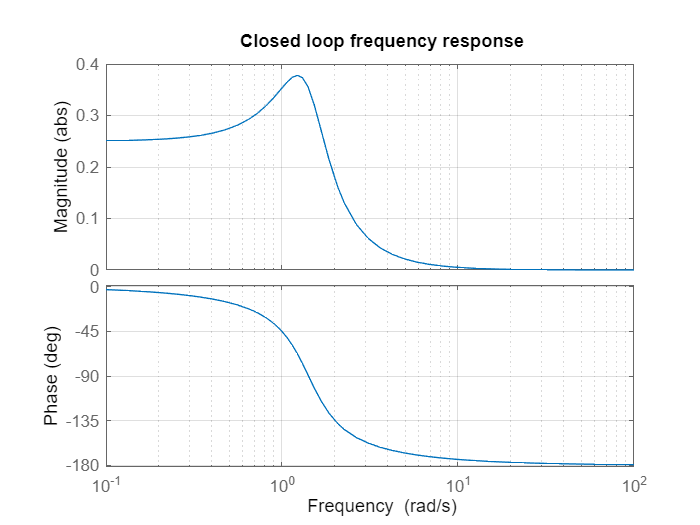

%omega = logspace(0, 100, 10000);
h = bodeplot(cLT);
title("Closed loop frequency response")

% For absolute units in Hz:
%setoptions(h,'FreqUnits','Hz','MagUnits', 'Abs');

% For absolute units in rad/s
setoptions(h, 'MagUnits', 'Abs')

grid on



% Finding bandwidth
bw = bandwidth(cLT);
fprintf("\nBandwidth: %f (rad/s) == %f (Hz)", bw, (bw/(2*pi)))


Bandwidth: 1.999052 (rad/s) == 0.318159 (Hz)



% Sensitivity analysis

fprintf("¬\n\n\n\n\n\nSensitivity Analysis -----------------------")

¬





Sensitivity Analysis -----------------------

S = 1/(1+cLT*G) % S = Y(S)/V(s)

S =
 
  4 s^4 + 8 s^3 + 18 s^2 + 14 s + 12
  ----------------------------------
  4 s^4 + 8 s^3 + 18 s^2 + 14 s + 13
 
Continuous-time transfer function.



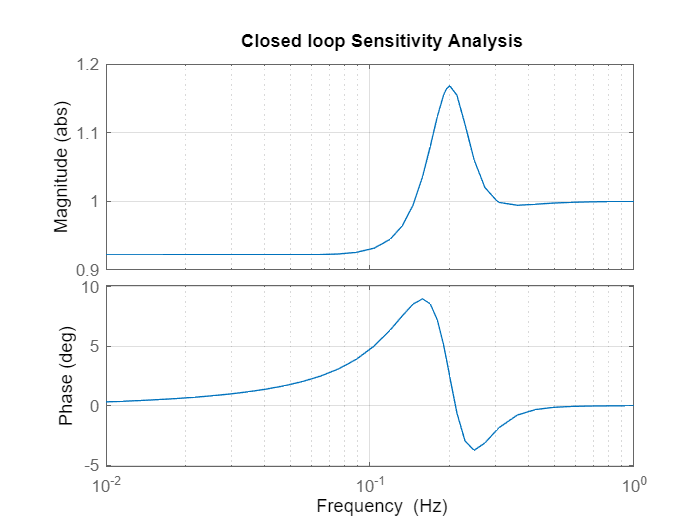


sensitivity = bodeplot(S);
title("Closed loop Sensitivity Analysis")
% For absolute units in Hz:
setoptions(sensitivity,'FreqUnits','Hz','MagUnits', 'Abs');


% For absolute units in rad/s
%setoptions(sensitivity, 'MagUnits', 'Abs')
grid on


DCsensitivityGain = dcgain(S)

DCsensitivityGain = 0.9231

[Gm,Pm,Wcg,Wcp] = margin(S);
gainCrossoverFreq = Wcp; % gain crossover frequency
fprintf("Gain crossover frequency: %f (rad/s) == %f (Hz)", gainCrossoverFreq, (gainCrossoverFreq/(2*pi)))

Gain crossover frequency: 0.926230 (rad/s) == 0.147414 (Hz)